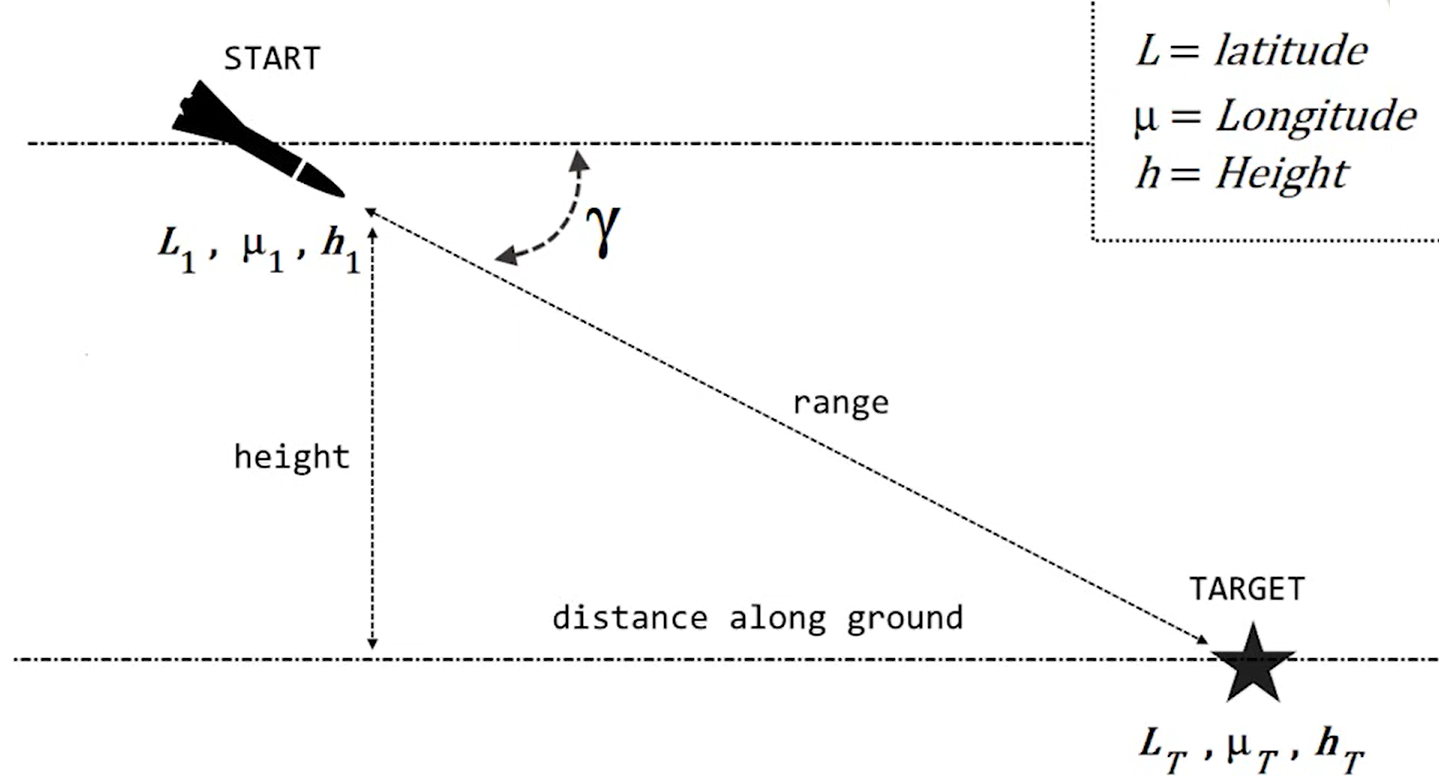

**Goal: **Control flight path $\gamma$ by using input $\delta_p$ to hit the target location. 

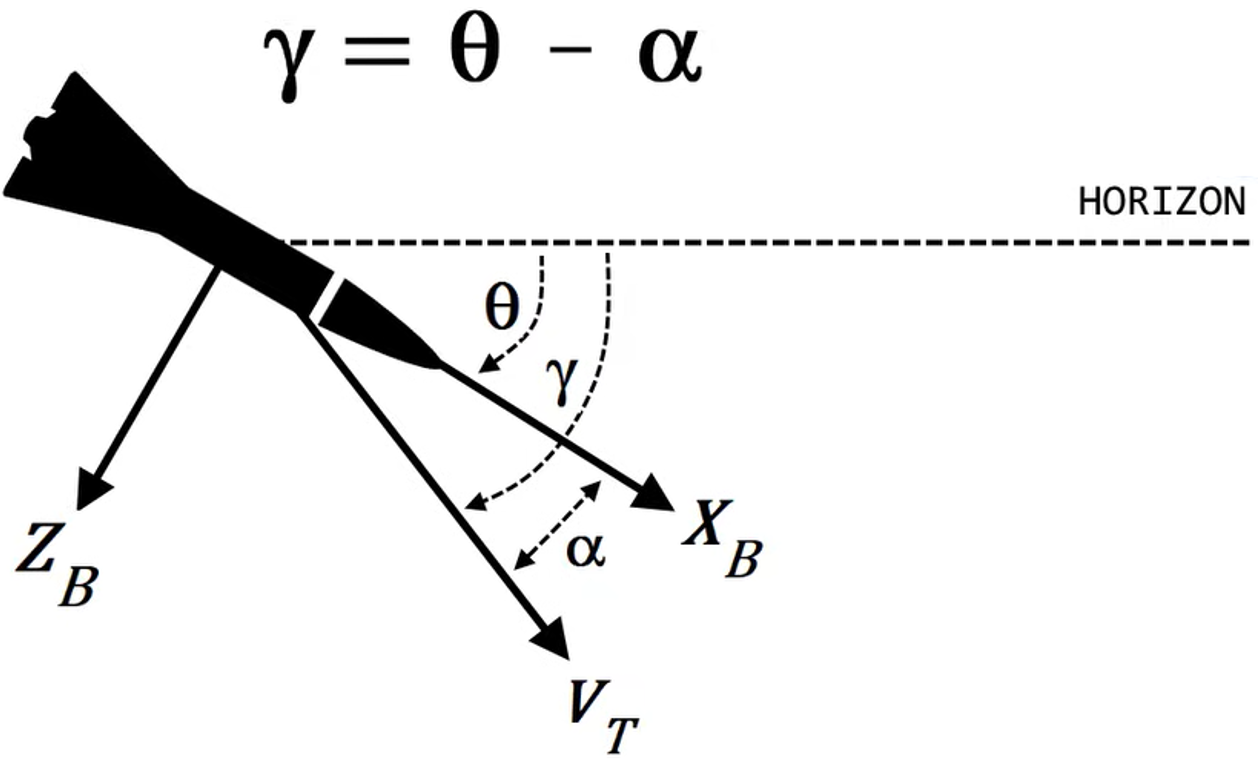

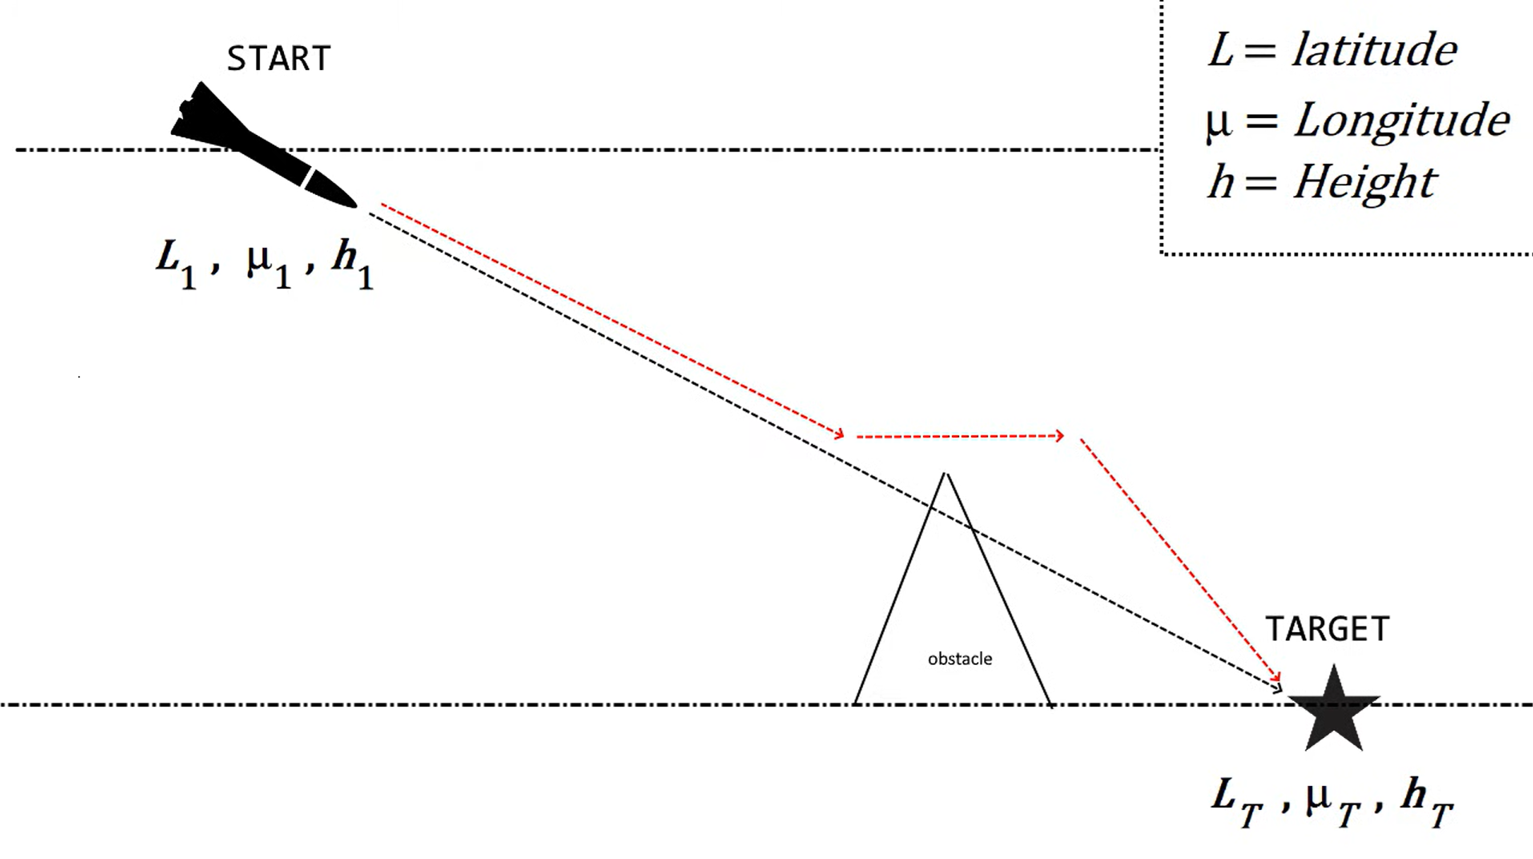

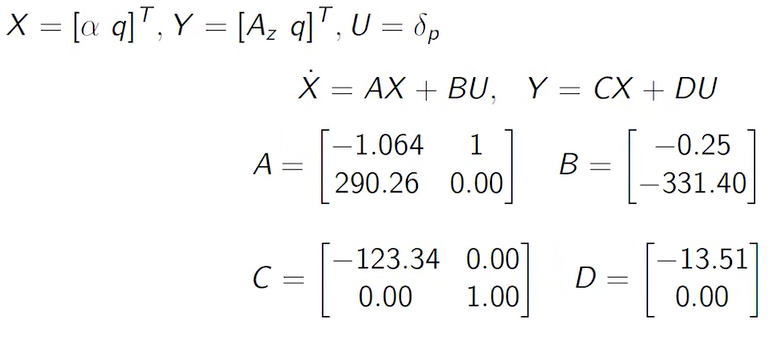

- $\alpha$ : angle of attack

- $q$ : pitch rate

- $Az$ : normal acceleration (along the body z-axis)

- $\delta_p$ : pitch control surface deflection

clc; close all; clear;
format short;

A = [-1.064,1;290.26,0];
B = [-0.25;-331.4];
C = [-123.34,0;0,1];
D = [-13.51;0];

states = {'AoA','q'};
inputs = {'\delta_c'};
outputs = {'Az','q'};

sys = ss(A,B,C,D, ...
      'statename',states,...
      'inputname',inputs,...
      'outputname',outputs)


sys =
 
  A = 
           AoA       q
   AoA  -1.064       1
   q     290.3       0
 
  B = 
        \delta_c
   AoA     -0.25
   q      -331.4
 
  C = 
          AoA       q
   Az  -123.3       0
   q        0       1
 
  D = 
       \delta_c
   Az    -13.51
   q          0
 
Continuous-time state-space model.



% TF
TFs = tf(sys);
TF = TFs(2,1)


TF =
 
  From input "\delta_c" to output "q":
    -331.4 s - 425.2
  ---------------------
  s^2 + 1.064 s - 290.3
 
Continuous-time transfer function.
Model Properties


disp(pole(TF));

  -17.5773
   16.5133



#### LQR

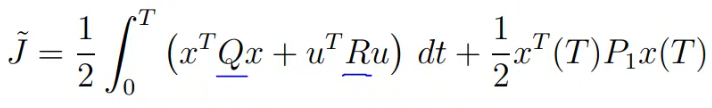

Q = [0.1 0; 0 0.1];
R = 0.5;

% LQR gain
[K,S,e] = lqr(A,B,Q,R);
% Xdot = AX + Bu = AX + B(-KX) = (A-BK)X

fprintf('eigenvalues of A-BK\n');

eigenvalues of A-BK


disp(eig(A-B*K));

   -2.5132
 -150.1351



fprintf('Feedback gain K');

Feedback gain K

disp(K);

   -1.4290   -0.4563



#### Closed loop system

Acl = A-B*K;
Bcl = B;
syscl = ss(Acl,Bcl,C,D, ...
        'statename',states,...
        'inputname',inputs,...
        'outputname',outputs);

TF = tf(syscl); % transfer function
TFc = TF(2,1)


TFc =
 
  From input "\delta_c" to output "q":
    -331.4 s - 425.2
  ---------------------
  s^2 + 152.6 s + 377.3
 
Continuous-time transfer function.
Model Properties


disp(pole(TF));

 -150.1351
   -2.5132



#### LQG Kalman filter design

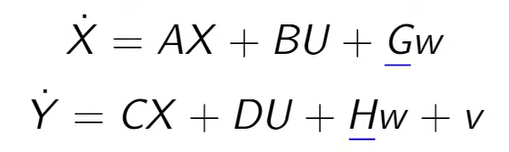

- G: n x n 

- w: n x 1 

- H: p x n 

- v: p x 1

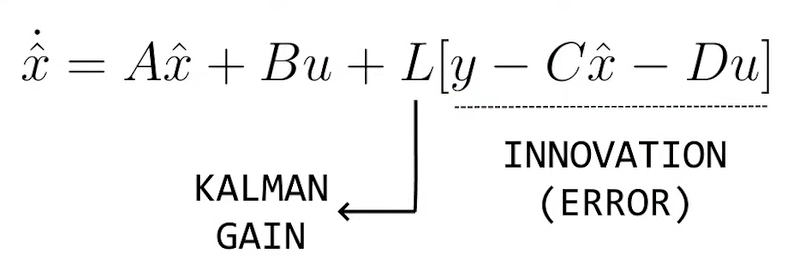

%LQG Kalman filter design 
G = eye(2);
H = zeros(2);
%Kalman Q, R noise matrices 
Qbar = diag(0.00015*ones(1,2)); 
Rbar = diag(0.55*ones(1,2));
%define noisy system
sys_n = ss(A, [B G], C, [D H]);
[kest,L,P] = kalman (sys_n, Qbar, Rbar, 0);
%kalman gain observer closed loop
Aob = A-L*C;
%display observer eigenvalues
fprintf('Observer eigenvalues\n');

Observer eigenvalues


disp(eig(Aob));

  -18.2152
  -15.9376



%noise time constants
dT1 = 0.75;
dT2 = 0.25;

#### Model parameters

R = 6371e3; %earth radius
Vel = 1021.08; %speed (m/s)
m2f = 3.2811; %meters to feet

%target location
LAT_TARGET = 34.6588;
LON_TARGET = -118.769745;
ELEV_TARGET = 795; %m - MSL

%initial location 
LAT_INIT = 34.2329; 
LON_INIT = -119.4573; 
ELEV_INIT = 10000; %m - MSL

%obstacle location
LAT_OBS = 34.61916;
LON_OBS = -118.8429;

%convert to radians 
d2r = pi/180;  %degrees to radians
l1 = LAT_INIT*d2r; 
u1 = LON_INIT *d2r; 
l2 = LAT_TARGET*d2r; 
u2 = LON_TARGET*d2r;
dl = l2-l1; 
du = u2-u1;

%haversine formula
a = sin(dl/2)^2 + cos(l1)*cos(l2)*sin(du/2)^2; %great circle distance
c = 2*atan2(sqrt(a),sqrt(1-a));
d = R*c; %horizontal distance

%initial range
r = sqrt(d^2+(ELEV_TARGET-ELEV_INIT)^2);

%initial azimuth (angle clockwise from North)
yaw_init = azimuth(LAT_INIT,LON_INIT,LAT_TARGET,LON_TARGET);
yaw = yaw_init*d2r;

%initial flight path angle
dh = abs(ELEV_TARGET-ELEV_INIT);
FPA_INIT = atan(dh/d);
